Part 1

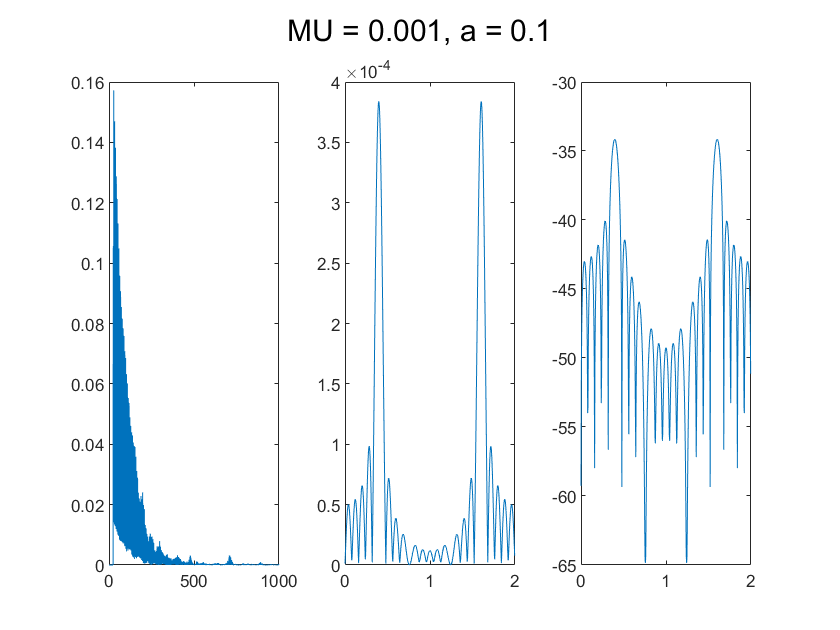

clc
clear
close all

M = 25;
L = 1000;
a = 0.1;
x = cos(2*pi*0.2*(0:(L-1))) + cos(2*pi*0.38*(0:(L-1)))+a*randn(1,L);
d = 0.4*cos(2*pi*0.2*(0:(L-1))+pi/5);

y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.001;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 3, 1);
plot(err_out.^2);


[H, W] = freqz(w, 1024, 'whole');
subplot(1, 3, 2);
plot(W/pi, abs(H));
subplot(1, 3, 3);
plot(W/pi, 10*log10(abs(H)));
sgtitle("MU = 0.001, a = 0.1");

Part 2

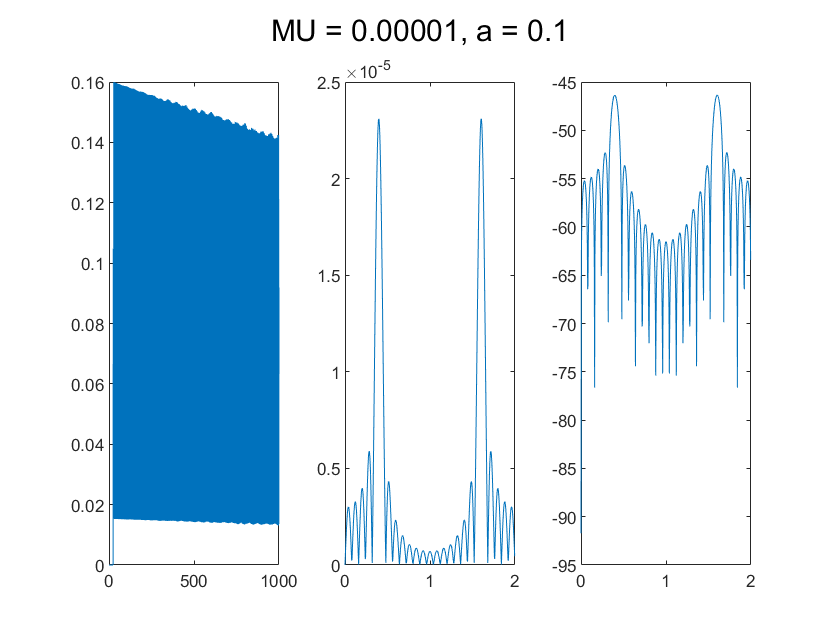

clc
clear
close all

%Mu = 0.00001
M = 25;
L = 1000;
a = 0.1;
x = cos(2*pi*0.2*(0:(L-1))) + cos(2*pi*0.38*(0:(L-1)))+a*randn(1,L);
d = 0.4*cos(2*pi*0.2*(0:(L-1))+pi/5);

y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.00001;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 3, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 3, 2);
plot(W/pi, abs(H));
subplot(1, 3, 3);
plot(W/pi, 10*log10(abs(H)));
sgtitle("MU = 0.00001, a = 0.1");

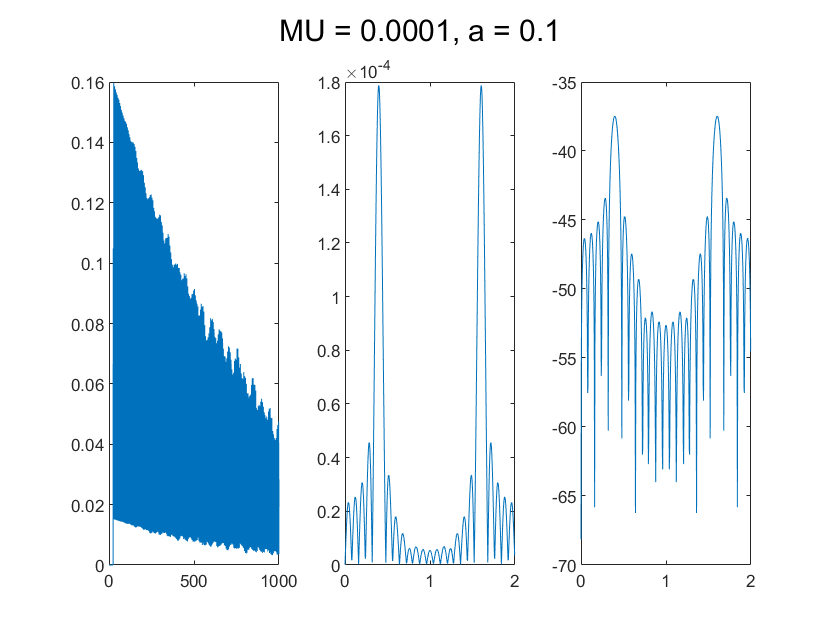

clc
clear
close all

%Mu = 0.0001
M = 25;
L = 1000;
a = 0.1;
x = cos(2*pi*0.2*(0:(L-1))) + cos(2*pi*0.38*(0:(L-1)))+a*randn(1,L);
d = 0.4*cos(2*pi*0.2*(0:(L-1))+pi/5);

y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.0001;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 3, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 3, 2);
plot(W/pi, abs(H));
subplot(1, 3, 3);
plot(W/pi, 10*log10(abs(H)));
sgtitle("MU = 0.0001, a = 0.1");

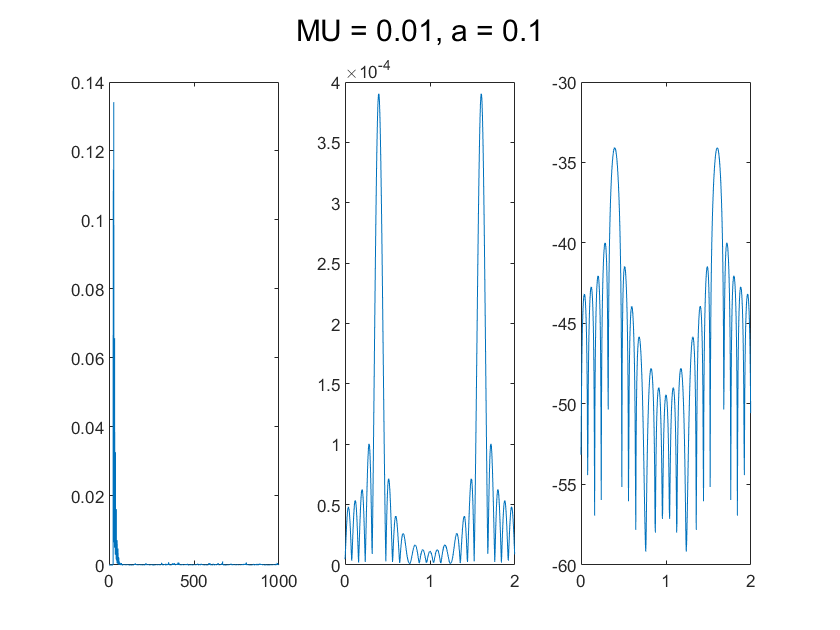

clc
clear
close all

%Mu = 0.01
M = 25;
L = 1000;
a = 0.1;
x = cos(2*pi*0.2*(0:(L-1))) + cos(2*pi*0.38*(0:(L-1)))+a*randn(1,L);
d = 0.4*cos(2*pi*0.2*(0:(L-1))+pi/5);

y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.01;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 3, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 3, 2);
plot(W/pi, abs(H));
subplot(1, 3, 3);
plot(W/pi, 10*log10(abs(H)));
sgtitle("MU = 0.01, a = 0.1");

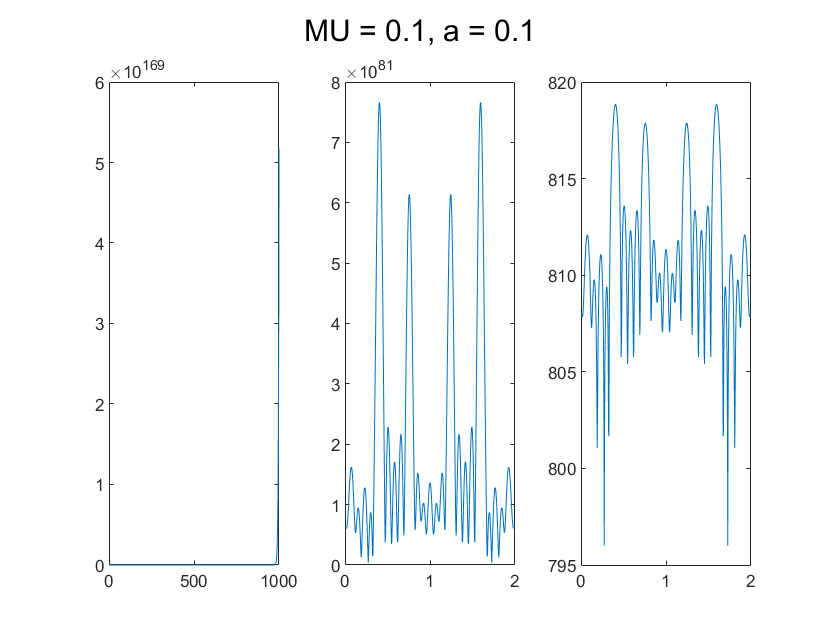

clc
clear
close all

%Mu = 0.1
M = 25;
L = 1000;
a = 0.1;
x = cos(2*pi*0.2*(0:(L-1))) + cos(2*pi*0.38*(0:(L-1)))+a*randn(1,L);
d = 0.4*cos(2*pi*0.2*(0:(L-1))+pi/5);

y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.1;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 3, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 3, 2);
plot(W/pi, abs(H));
subplot(1, 3, 3);
plot(W/pi, 10*log10(abs(H)));
sgtitle("MU = 0.1, a = 0.1");

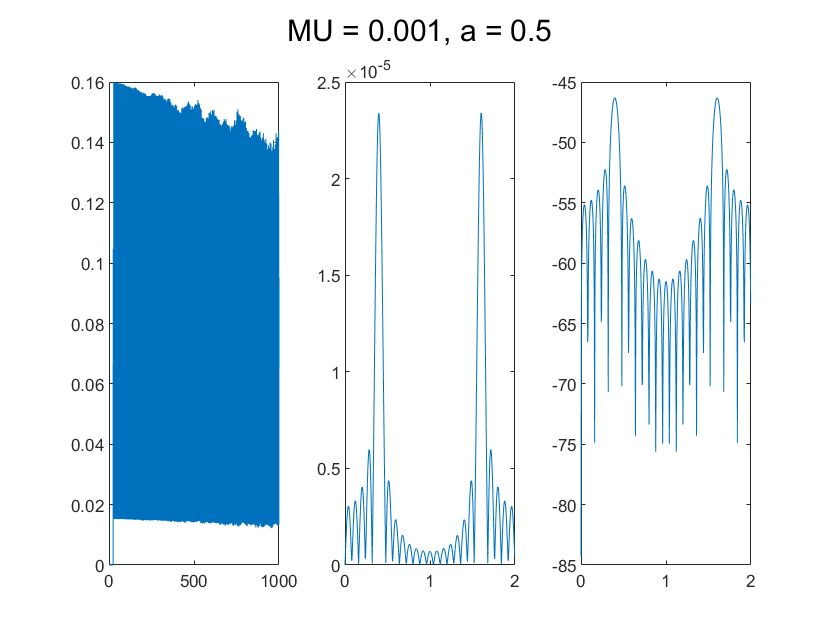

clc
clear
close all

%Mu = 0.00001
M = 25;
L = 1000;
a = 0.5;
x = cos(2*pi*0.2*(0:(L-1))) + cos(2*pi*0.38*(0:(L-1)))+a*randn(1,L);
d = 0.4*cos(2*pi*0.2*(0:(L-1))+pi/5);

y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.00001;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 3, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 3, 2);
plot(W/pi, abs(H));
subplot(1, 3, 3);
plot(W/pi, 10*log10(abs(H)));
sgtitle("MU = 0.001, a = 0.5");

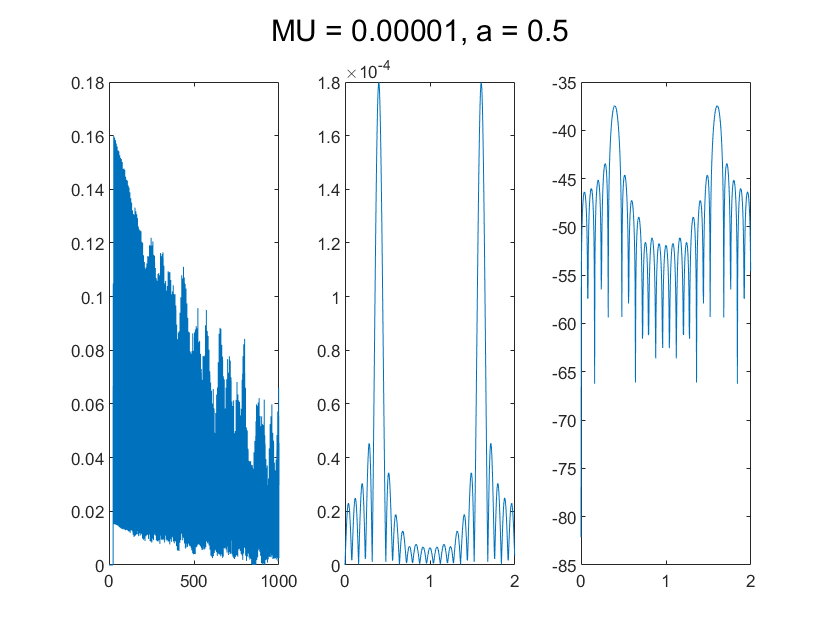

clc
clear
close all

%Mu = 0.0001
M = 25;
L = 1000;
a = 0.5;
x = cos(2*pi*0.2*(0:(L-1))) + cos(2*pi*0.38*(0:(L-1)))+a*randn(1,L);
d = 0.4*cos(2*pi*0.2*(0:(L-1))+pi/5);

y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.0001;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 3, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 3, 2);
plot(W/pi, abs(H));
subplot(1, 3, 3);
plot(W/pi, 10*log10(abs(H)));
sgtitle("MU = 0.00001, a = 0.5");

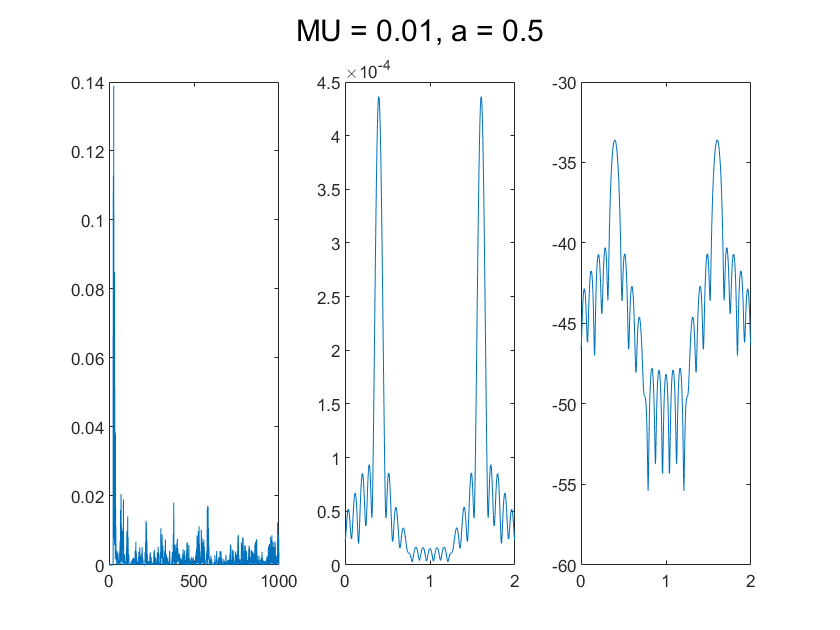

clc
clear
close all

%Mu = 0.01
M = 25;
L = 1000;
a = 0.5;
x = cos(2*pi*0.2*(0:(L-1))) + cos(2*pi*0.38*(0:(L-1)))+a*randn(1,L);
d = 0.4*cos(2*pi*0.2*(0:(L-1))+pi/5);

y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.01;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 3, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 3, 2);
plot(W/pi, abs(H));
subplot(1, 3, 3);
plot(W/pi, 10*log10(abs(H)));
sgtitle("MU = 0.01, a = 0.5");

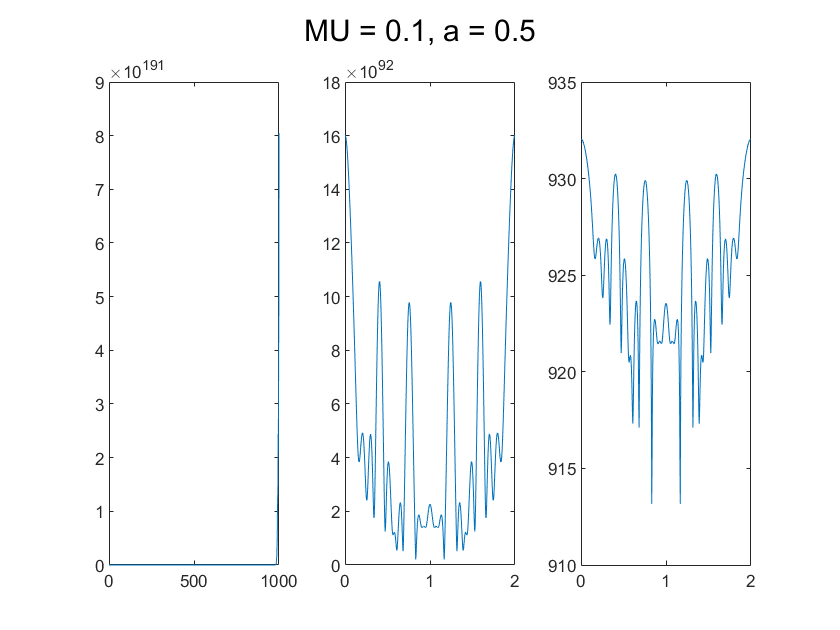

clc
clear
close all

%Mu = 0.1
M = 25;
L = 1000;
a = 0.5;
x = cos(2*pi*0.2*(0:(L-1))) + cos(2*pi*0.38*(0:(L-1)))+a*randn(1,L);
d = 0.4*cos(2*pi*0.2*(0:(L-1))+pi/5);

y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.1;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 3, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 3, 2);
plot(W/pi, abs(H));
subplot(1, 3, 3);
plot(W/pi, 10*log10(abs(H)));
sgtitle("MU = 0.1, a = 0.5");

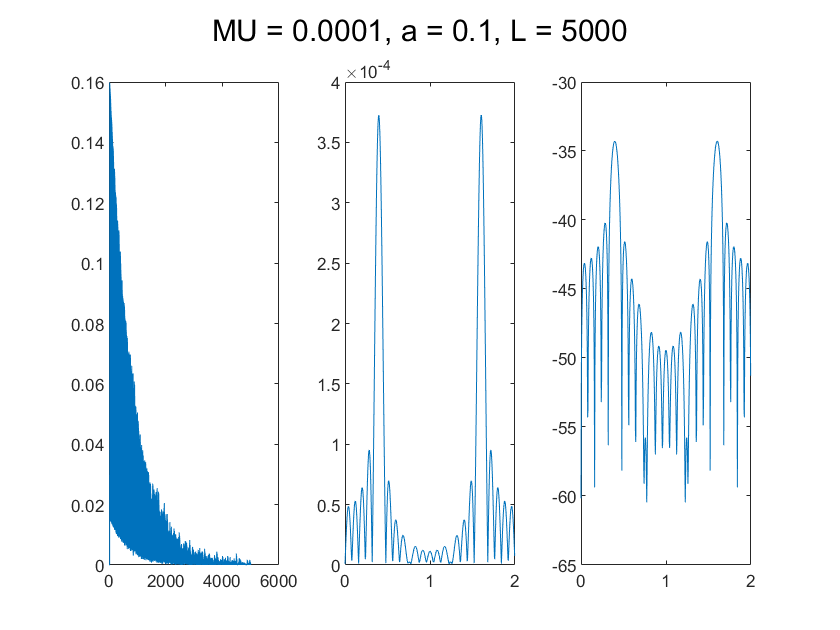

clc
clear
close all

M = 25;
L = 5000;
a = 0.1;
x = cos(2*pi*0.2*(0:(L-1))) + cos(2*pi*0.38*(0:(L-1)))+a*randn(1,L);
d = 0.4*cos(2*pi*0.2*(0:(L-1))+pi/5);

y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.0001;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 3, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 3, 2);
plot(W/pi, abs(H));
subplot(1, 3, 3);
plot(W/pi, 10*log10(abs(H)));
sgtitle("MU = 0.0001, a = 0.1, L = 5000");

Part 3

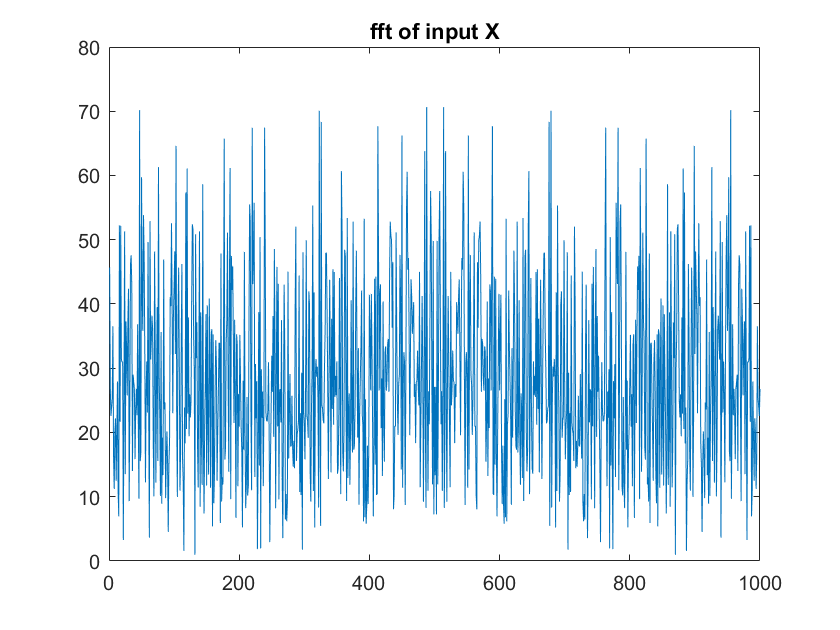

M = 25;
L = 1000;
h = [1, 0, 0, 0, 0, 0, 0.5];
x = randn(1,L);
x_unk = conv(h,x);
d = x_unk(1: end- length(h)+1); 

X = fft(x);
D = fft(d);


figure;
plot(abs(X));
title("fft of input X");

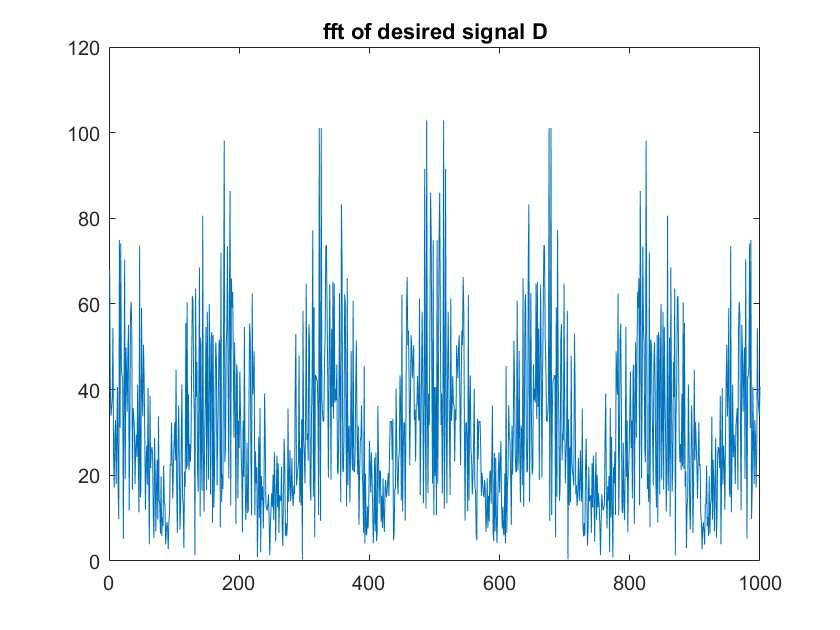


figure;
plot(abs(D));
title("fft of desired signal D");

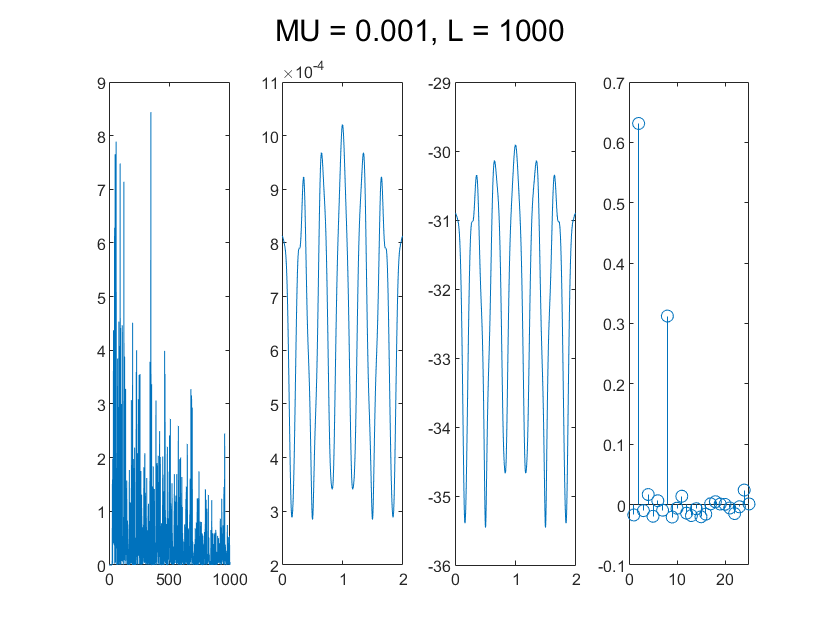


y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.001;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 4, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 4, 2);
plot(W/pi, abs(H));
subplot(1, 4, 3);
plot(W/pi, 10*log10(abs(H)));
subplot(1, 4, 4);
stem(w);
sgtitle("MU = 0.001, L = 1000");

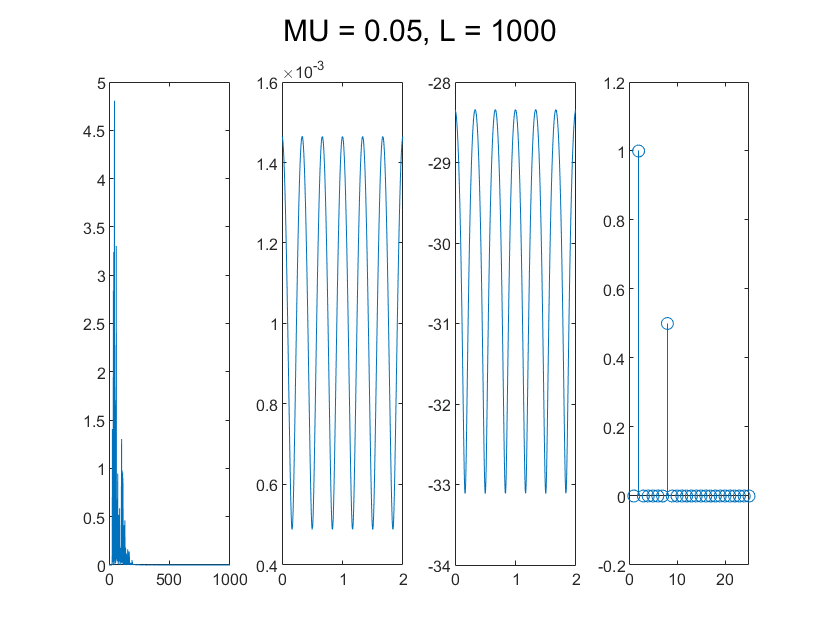

y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.05;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 4, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 4, 2);
plot(W/pi, abs(H));
subplot(1, 4, 3);
plot(W/pi, 10*log10(abs(H)));
subplot(1, 4, 4);
stem(w);
sgtitle("MU = 0.05, L = 1000");

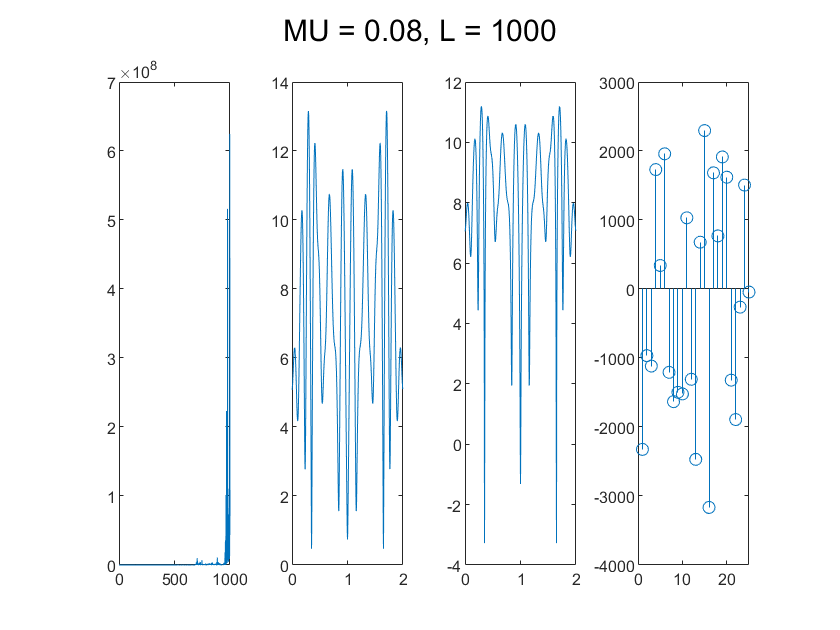

y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.08;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 4, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 4, 2);
plot(W/pi, abs(H));
subplot(1, 4, 3);
plot(W/pi, 10*log10(abs(H)));
subplot(1, 4, 4);
stem(w);
sgtitle("MU = 0.08, L = 1000");

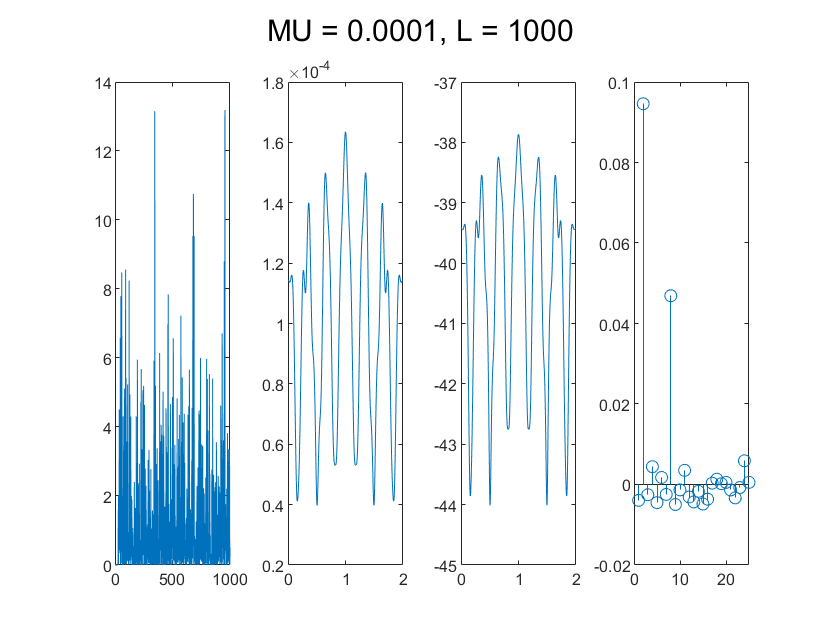

y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.0001;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 4, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 4, 2);
plot(W/pi, abs(H));
subplot(1, 4, 3);
plot(W/pi, 10*log10(abs(H)));
subplot(1, 4, 4);
stem(w);
sgtitle("MU = 0.0001, L = 1000");

y_out = zeros(L, 1);
err_out = zeros(L, 1);

w = zeros(M, 1);

mu = 0.01;

d = x_unk(length(h):end);
figure;
plot(abs(X));
title("fft of input X");


figure;
plot(abs(D));
title("fft of desired signal D");

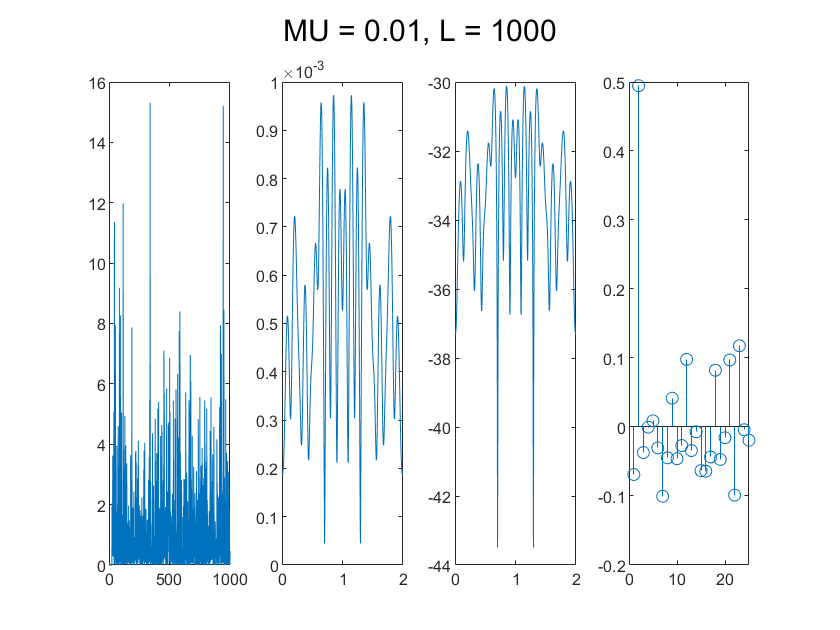


for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 4, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 4, 2);
plot(W/pi, abs(H));
subplot(1, 4, 3);
plot(W/pi, 10*log10(abs(H)));
subplot(1, 4, 4);
stem(w);
sgtitle("MU = 0.01, L = 1000");

Step 4

M = 25;
L = 1000;
f_pm = [0, 1200, 1600, 2400, 2800, 4000]/4000;
a_pm = [0,0,1,1,0,0];
n_pm = 64;
b_pm = firpm(n_pm, f_pm, a_pm);
x = randn(1,L);
x_unk = conv(b_pm, x);
d = x_unk(1: end- length(b_pm)+1); 

figure;
plot(abs(X));
title("fft of input X");


figure;
plot(abs(D));
title("fft of desired signal D");

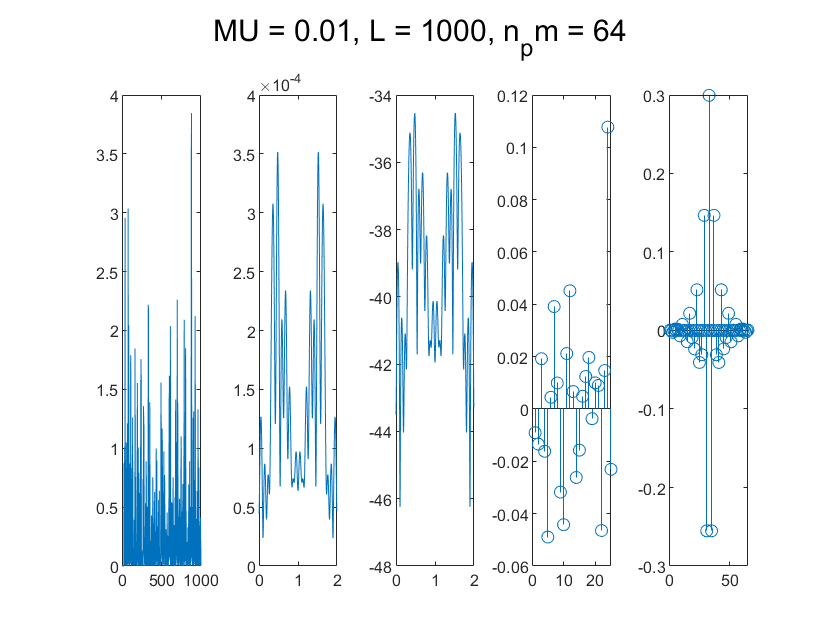


mu = 0.01;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 5, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 5, 2);
plot(W/pi, abs(H));
subplot(1, 5, 3);
plot(W/pi, 10*log10(abs(H)));
subplot(1, 5, 4);
stem(w);
subplot(1, 5, 5);
stem(b_pm);
sgtitle("MU = 0.01, L = 1000, n_pm = 64");


M = 25;
L = 1000;
f_pm = [0, 1200, 1600, 2400, 2800, 4000]/4000;
a_pm = [0,0,1,1,0,0];
n_pm = 32;
b_pm = firpm(n_pm, f_pm, a_pm);
x = randn(1,L);
x_unk = conv(b_pm, x);
d = x_unk(1: end- length(b_pm)+1); 

figure;
plot(abs(X));
title("fft of input X");


figure;
plot(abs(D));
title("fft of desired signal D");

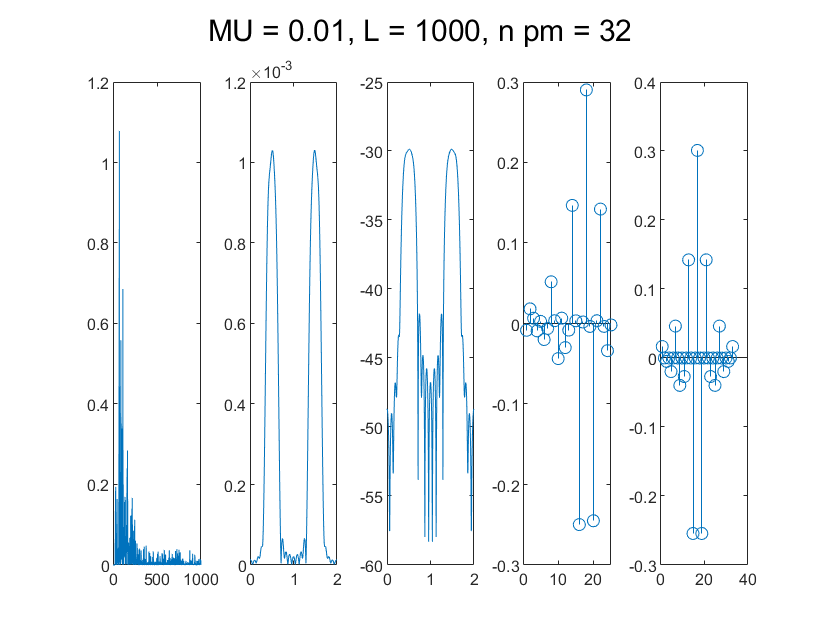


mu = 0.01;

for n = M:L
    
    xn_index = 1;

    for j = n:-1:n-M+1
        xn(xn_index) = x(mod(j, L) + 1);
        xn_index = xn_index + 1;
    end
    
    yn = dot(transpose(w), xn);

    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    
    w = w + mu*en*transpose(xn);
end

figure;
subplot(1, 5, 1);
plot(err_out.^2);

[H, W] = freqz(w, 1024, 'whole');
subplot(1, 5, 2);
plot(W/pi, abs(H));
subplot(1, 5, 3);
plot(W/pi, 10*log10(abs(H)));
subplot(1, 5, 4);
stem(w);
subplot(1, 5, 5);
stem(b_pm);


sgtitle("MU = 0.01, L = 1000, n pm = 32");